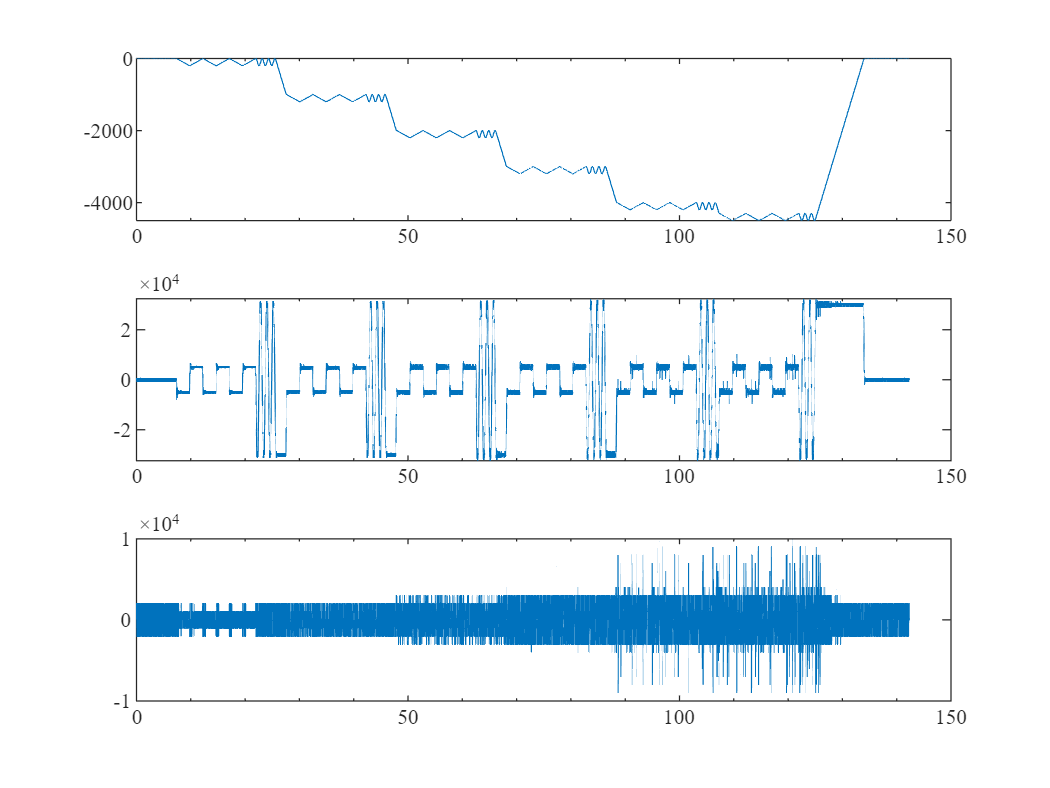

% FILE_PATH = char('D:\WorkingDir\Experiments\202406-mms-dynamics\ids results mat\20240529 IDS\DYB_A3J40.mat');
FILE_PATH = char('D:\WorkingDir\Experiments\202406-mms-dynamics\ids results mat\20240530 IDS\XD_Y3000_A3J80.mat');
idsData = load(FILE_PATH);
idsData = struct2table(idsData); 

figure; 
tiledlayout(3,1); 

ax1 = nexttile; 
DOWN_SAMPLE_RATE = 1;
idsData.Time = idsData.Time(1:DOWN_SAMPLE_RATE:end);
idsData.Displacement = idsData.Displacement(1:DOWN_SAMPLE_RATE:end);
plot(ax1, idsData.Time, idsData.Displacement);
hold(ax1, "on");

ax2 = nexttile;
idsData.veloTime = 0.5 * (idsData.Time(1:end - 1) + idsData.Time(2:end));
idsData.velo = 60 * diff(idsData.Displacement) ./ diff(idsData.Time);
plot(ax2, idsData.veloTime, idsData.velo);
hold(ax2, "on");


ax3 = nexttile;
idsData.accelTime = 0.5 * (idsData.veloTime(1:end - 1) + idsData.veloTime(2:end));
idsData.accel = diff(idsData.velo) ./ diff(idsData.veloTime) ./ 60000;
plot(ax3, idsData.accelTime, idsData.accel);
hold(ax3, "on");

linkaxes([ax1,ax2,ax3],'x');